**EXP. 10: Median Filter and Application of Filtering Techniques**

**Name :- P.Sai Uttej**

**Reg ID:-19BCE7163**

1.Question

Given the noisy image. Apply filtering approach to remove the noise. Which filter is preferred in this case? 

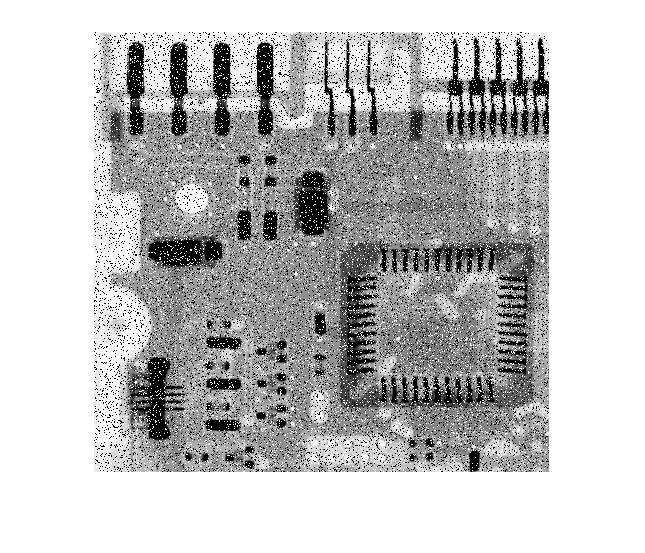

clc
close all
clear
img=imread('Ckt_noise.tif');   %reading image into img variable
imshow(img)                    %Displaying image

img2=zeros(size(img)+2);       %for padding purpose
imgnew=zeros(size(img));
imgnew=median_filter(img,img2,imgnew)   %user defined function

imgnew =      0   246   249   249   246   239   232   228   210   206   206   200   225   213   218   218   231   233   236   240   242   242   242   242   243   243   244   245   246   248   248     0     0   248   248   248   248     0   248   248   248   248   248   248   248   248   248   248   248   248
     0   249   250   249   249   243   233   228   218   206   206   200   225   213   218   225   231   233   236   242   242   242   242   242   243   243   244   245   246   248   248   248   248   248   248   248   248   245   248   248   248   248   248   248   248   248   248   248   248   248
     0   248   249   248   243   233   228   218   210   200   194   186   186   195   208   210   225   231   234   235   239   239   239   239   240   240   241   243   245   246   244   242   243   247   248   247   245   245   245   245   245   246   245   245   245   245   245   245   246   245
     0   248   248   247   242   233   222   218   215   199   187   184   184   186   1

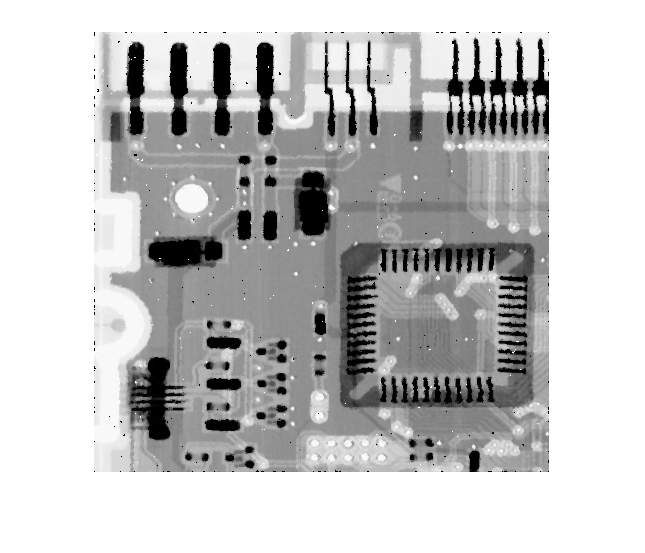

imgnew=uint8(imgnew);
imshow(imgnew);

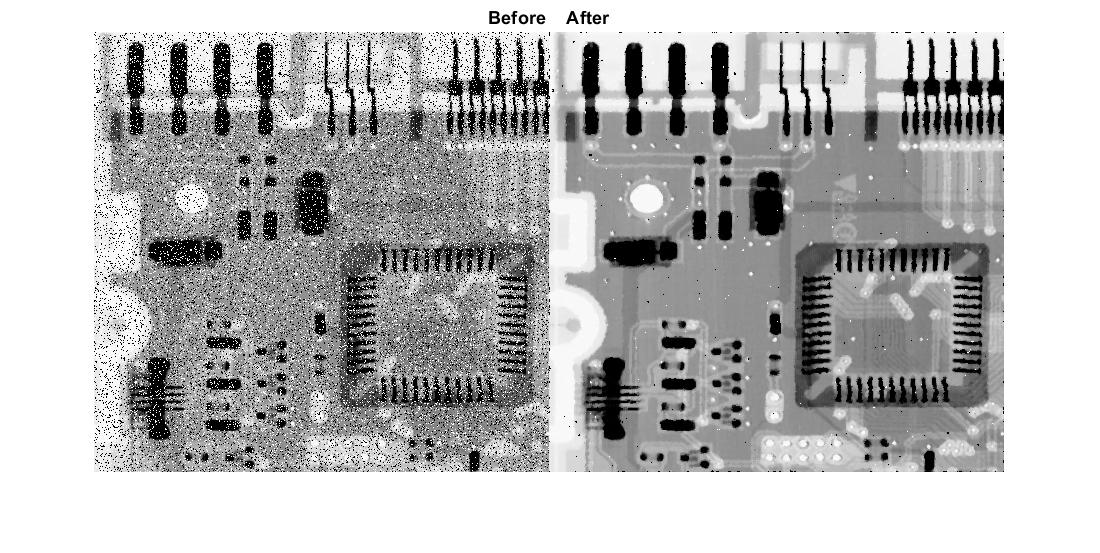

imshowpair(img,imgnew,'montage')    %showing both images together
title('Before    After')

**median_filter.m (function code)**

function [imgnew]=median_filter(img,img2,imgnew)

    for x=1:size(img,1)

    for y=1:size(img,2)

        img2(x+1,y+1)=img(x,y);

    end

end

for i= 1:size(img2,1)-2

    for j=1:size(img2,2)-2

        window=zeros(9,1);

        inc=1;

    for x=1:3

        for y=1:3

            window(inc)=img2(i+x-1,j+y-1);

            inc=inc+1;

        end

    end

    med=sort(window);

    imgnew(i,j)=med(5);

    end

end

end

**2.Question**

Given a space image. Apply image processing techniques to segment the brighter and larger group of pixels present in the image. (remove the unwanted details from the image) 

Provide all the details of your solution. 

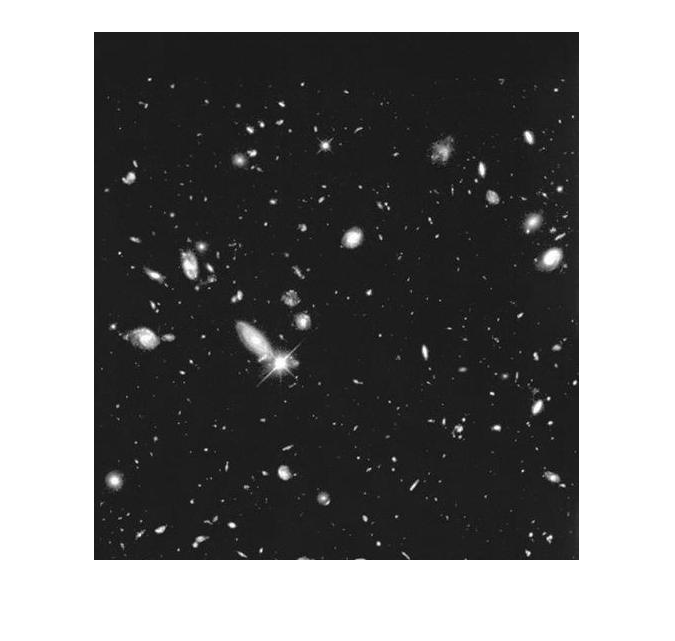

clc
close all
clear
img=imread('Hubble.tif');       %reading image into img variable
imshow(img)

img3=imgaussfilt(img)           %Gaussian filtering is used to remove noise and detail It.

img3 = 528×485 uint8 matrix
   29   29   29   29   29   29   29   29   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28
   29   29   29   29   29   29   29   29   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28
   29   29   29   29   29   29   29   29   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28
   29   29   29   29   29   29   29   29   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   2

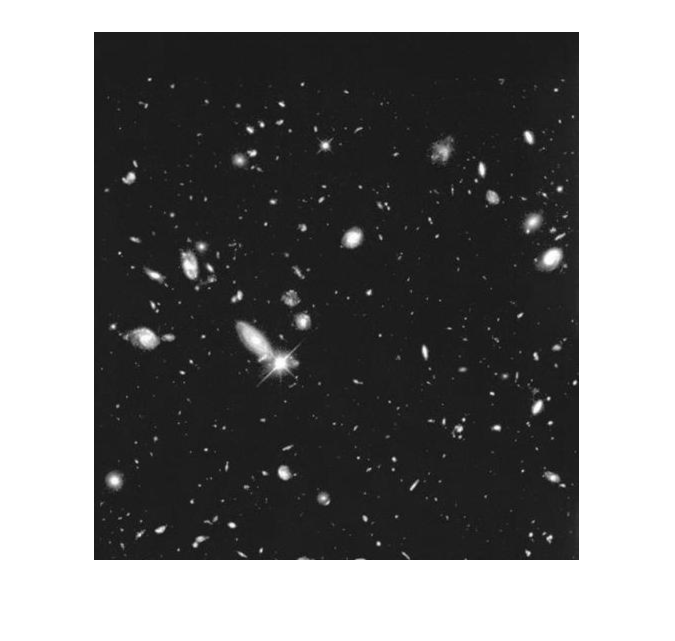

imshow(img3);

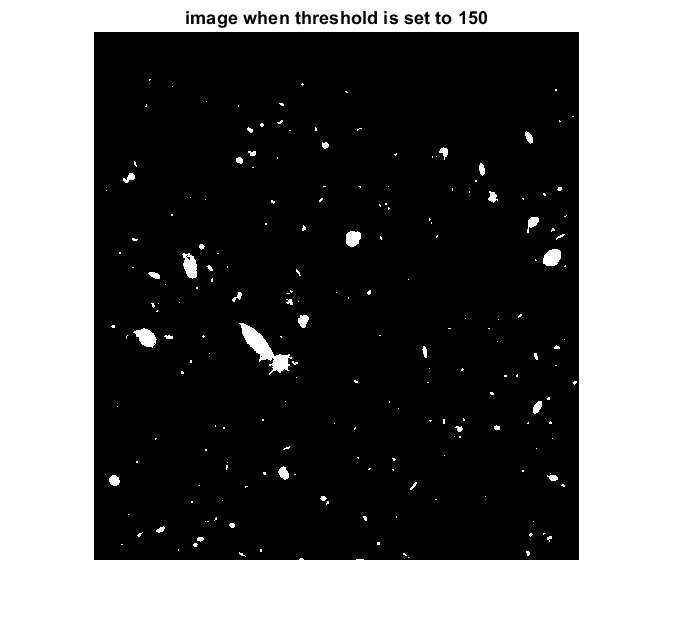

[m,n]=size(img3);
for i=1:m
 for j=1:n
 if (img(i,j)<=150)             %If pixel intensity is less then 150 then setting to 0
 imgnew1(i,j)=0;
 elseif(img(i,j)>150)           %else if grater then 150 setting to as it is.
 imgnew1(i,j)=img3(i,j);
 end
 end
end
imshow(imgnew1);
title('image when threshold is set to 150')

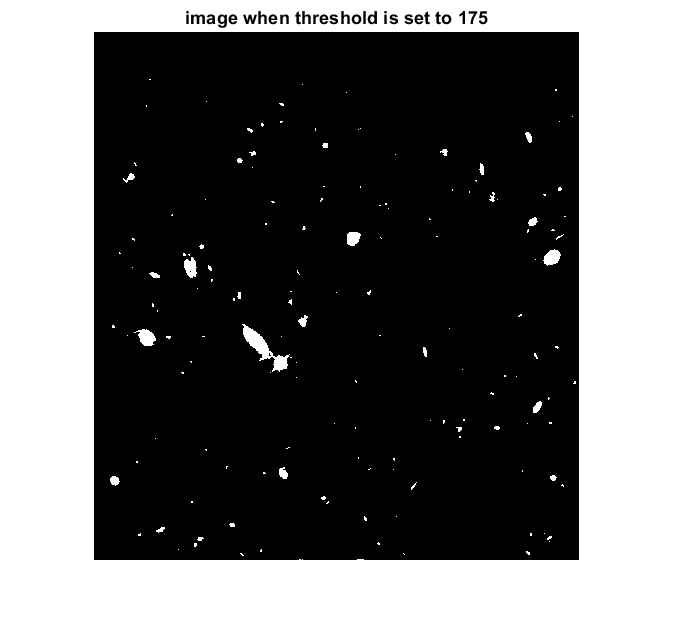




for i=1:m
 for j=1:n
 if (img(i,j)<=175)         %If pixel intensity is less then 175 then setting to 0
 imgnew2(i,j)=0;
 elseif(img(i,j)>175)
 imgnew2(i,j)=img3(i,j);    %else if greater then 175 setting to as it is.
 end
 end
end
imshow(imgnew2);
title('image when threshold is set to 175')

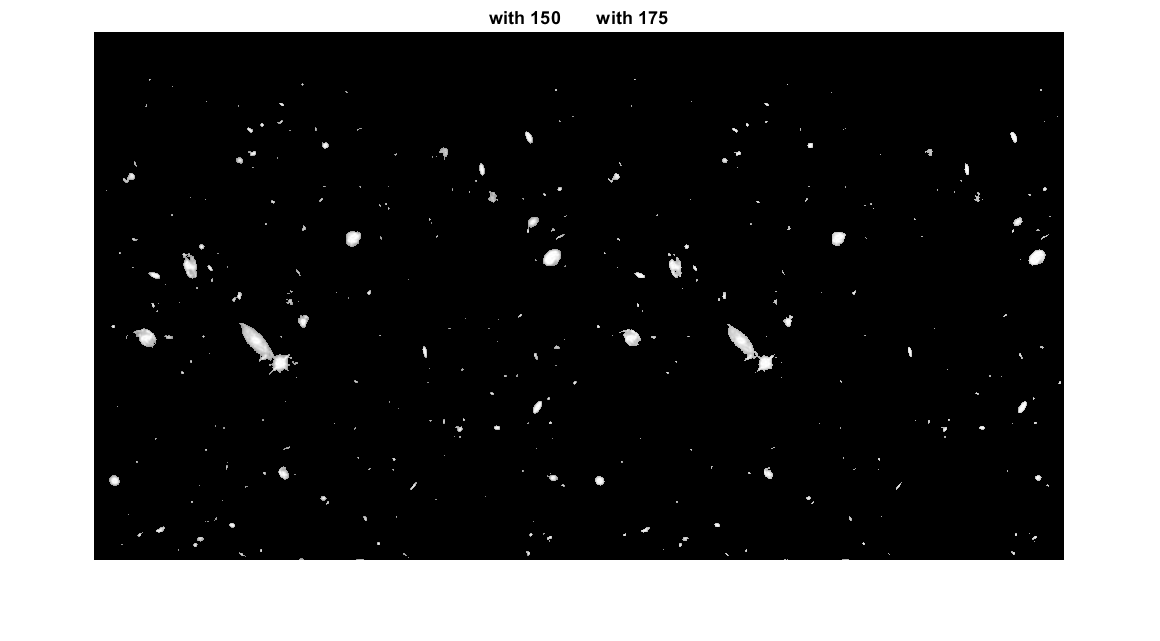

imshowpair(imgnew1,imgnew2,'montage');      %showing both images together
title('with 150       with 175' );

%Compare to 150 image 175 image is good filtered.

**3.Question**

Given the moon image, apply Laplacian filter on it. And then subtract the Laplacian filter from the original image to get the enhanced image.  

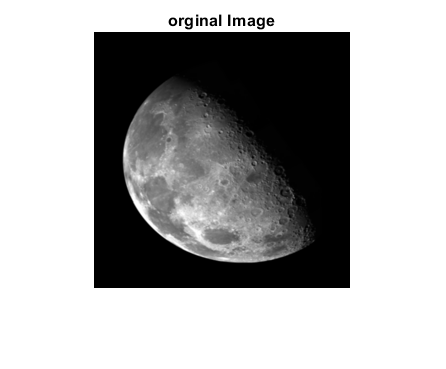

clc
close all
clear
img=imread('Moon.tif');      %reading moon imag
img1=imresize(img,[256,256]);%resizeing image into 256*256
imshow(img1);                %displaying img1's image
title('orginal Image')

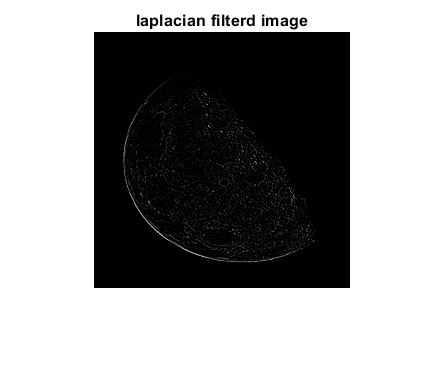

[m,n]=size(img1);             %initializing the size of image into m and n variables
imgpad = zeros(258,258);     %assigning the imgpad to zeros 258 rows and 258 coloumns .
imgpad(2:257,2:257)=img1;

laplacian_mask=[0 -1 0 ;-1 4 -1;0 -1 0];
op=convulution_user(imgpad,m,n,laplacian_mask);  %user defined function
imshow(uint8(op));
title('laplacian filterd image')

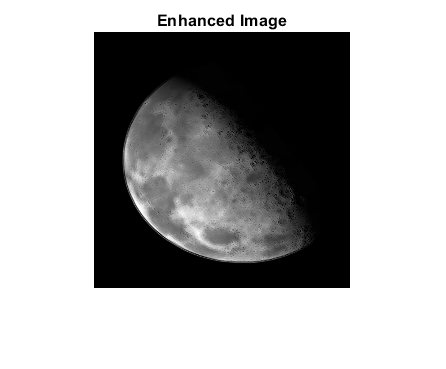

imgenhan=imsubtract(img1,uint8(op));
imshow(imgenhan);
title('Enhanced Image');    %After Subtraction of laplacian filtered image from orginal image

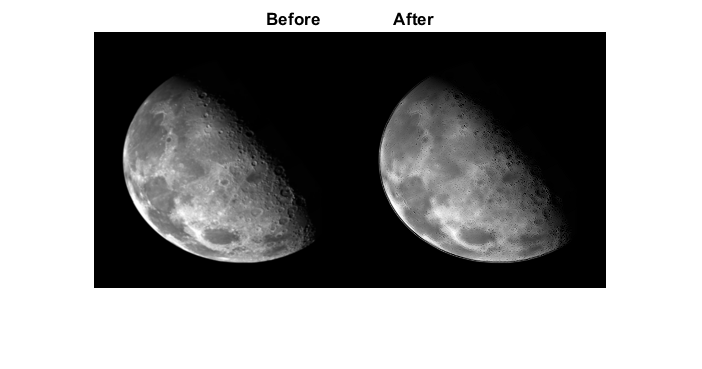

imshowpair(img1,imgenhan,'montage');    %showing both images together
title('Before               After');